# Lesson 9: Creating Video Montage and Flipbooks

## Creating a GIF from an Animation Sheet

With your sidekicks permission, you can find animation sheets on the internet by performing an image search for things like "animation frames," "sprite sheet," or "printable flip book."  To use an image with this script, it must have the following grid format:

## 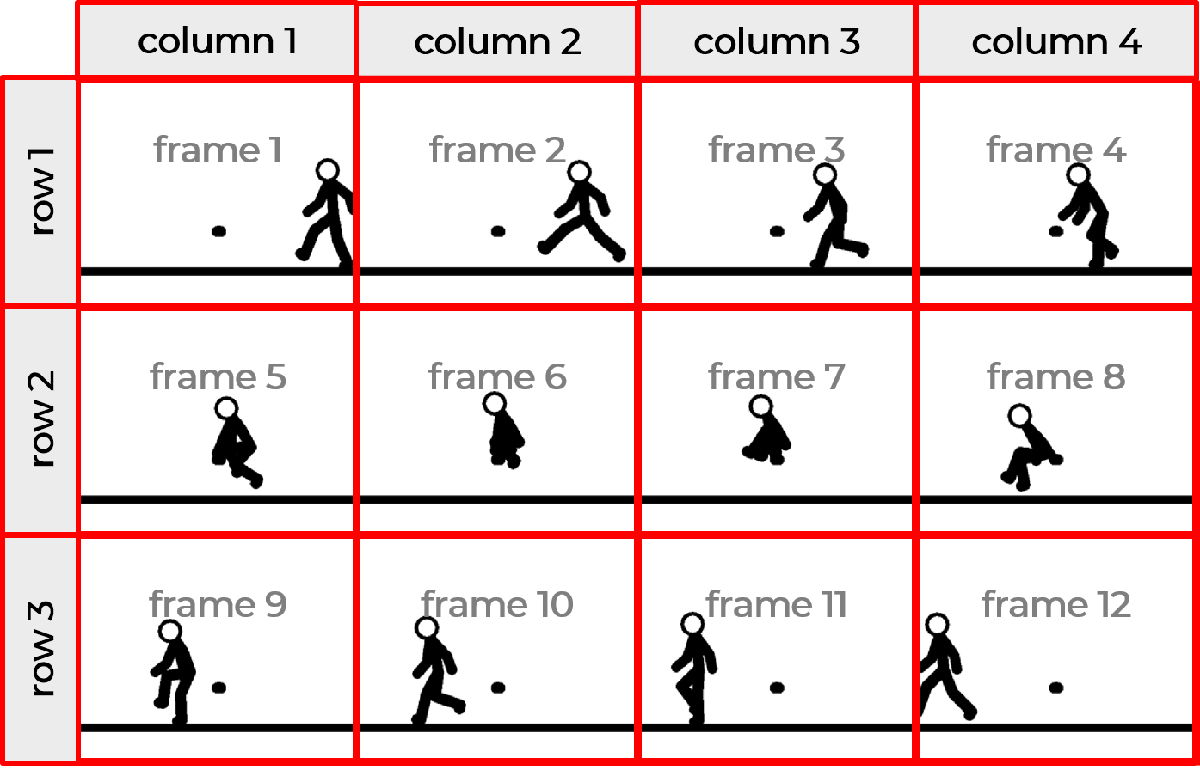

## Load an Animation Sheet

Once you find an animation sheet you like, view the full image and copy and paste the link location into the string variable named `file` below (or save the image to this folder and type the file name into the string variable named `file` below).

file = "https://cdnb.artstation.com/p/assets/images/images/003/823/759/large/noah-brandow-dino-sprite-all-rows-4-smaller.jpg";
sheet = imread(file);

close all
imshow(sheet)

Count the number of rows and columns of frames on the sheet (like the figure above) and store these values in the variables named `nRows` and `nCols`, respectively.  You can speed-up or slow-down the animation by decreasing or increasing the time pause (seconds) between frames, using the variable `dt`.

nRows = 7;
nCols = 8;
dt = 0.1;

## Loop Through Frames Inset in Animation Sheet

You do not need to edit any of the code below.

% Change file name extension to .gif
[~,gifName] = fileparts(file);
gifName = gifName + ".gif";

sz = size(sheet); % size of full sheet image
frameRows = floor(sz(1)/nRows);  % rows of pixels in each frame
frameCols = floor(sz(2)/nCols);  % columns of pixels in each frame

figure("Visible","on")
k = 0; % frame counter
for i = 1:nRows
    % Set rows to extract current frame from full sheet image
    rows = (1:frameRows) + (i-1)*frameRows;
    for j = 1:nCols
        % Set columns to extract current frame from full sheet image
        cols = (1:frameCols) + (j-1)*frameCols;
        k = k + 1; % increment frame counter
        
        % Extract current frame from full sheet image
        frame = sheet(rows,cols,:);
        imshow(frame)
        pause(dt)

        % Write frame to *.gif file
        [img,cmap] = rgb2ind(frame,256); % convert to indexed image
        if (k == 1)
            imwrite(img,cmap,gifName,"gif",LoopCount=Inf,DelayTime=dt);
        else
            imwrite(img,cmap,gifName,"gif",WriteMode="append",DelayTime=dt);
        end
    end
end